Discretizamos el sistema continuo.

motorCont = ss(A,B,C,D);
T = 1e-4;
motorDisc = c2d(motorCont,T);
F = motorDisc.A;
G = motorDisc.B;

Recalculamos los polos de la realimentación, el integrador y el estimador.

F_ri = [F zeros(2,1); T*C 1];
G_ri = [G; 0];
poles_ri_disc = exp([-0.3*p -0.35*p -0.4*p]*T);
K_ri_disc = place(F_ri,G_ri,poles_ri_disc);
K_r_disc = K_ri_disc(1:2);
K_i_disc = K_ri_disc(3);
poles_e_disc = exp([-0.65*p -0.6*p]*T);
L_disc = place(F',C',poles_e_disc)';

Constantes.

k_awp = 0;
accDirDisc = ( C*( (eye(2)-(F-G*K_r_disc))^-1 * G ) )^-1;
accInt = 1;

Se simula con la acción directa correcta y acción integral.

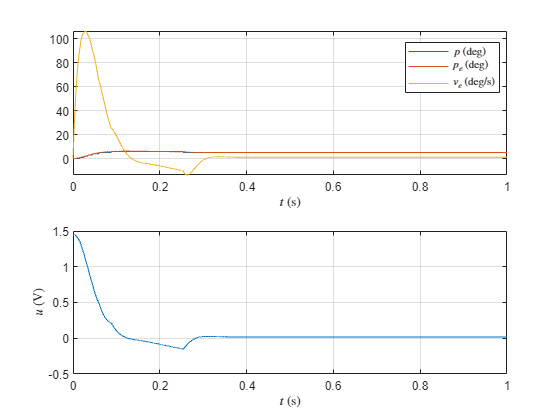

open('controller_disc.slx')

simOut = sim('controller_disc.slx');
time = simOut.tout;
angPos = simOut.yout{1}.Values.Data;
voltage = simOut.yout{3}.Values.Data;
angPosEst = simOut.yout{4}.Values.Data;
angVelEst = simOut.yout{5}.Values.Data;

figure
subplot(2,1,1)
plot(time,angPos)
hold on
plot(time,angPosEst)
plot(time,angVelEst)
grid on
legend('$p$ (deg)','$p_e$ (deg)','$v_e$ (deg/s)', Location="best", Interpreter='latex')
xlabel('$t$ (s)', Interpreter='latex')
xlim([0 1])
subplot(2,1,2)
plot(time,voltage)
grid on
xlabel('$t$ (s)', Interpreter='latex')
ylabel('$u$ (V)', Interpreter='latex')
xlim([0 1])
exportgraphics(gcf,'figuras\accionDirectaDisc.pdf')

Sin acción integral.

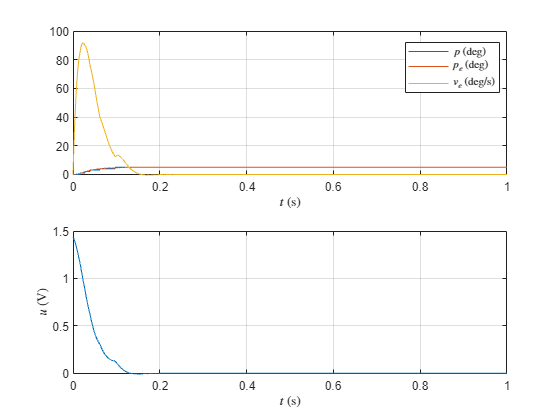

accInt = 0;
simOut = sim('controller_disc.slx');
time = simOut.tout;
angPos = simOut.yout{1}.Values.Data;
voltage = simOut.yout{3}.Values.Data;
angPosEst = simOut.yout{4}.Values.Data;
angVelEst = simOut.yout{5}.Values.Data;

figure
subplot(2,1,1)
plot(time,angPos)
hold on
plot(time,angPosEst)
plot(time,angVelEst)
grid on
legend('$p$ (deg)','$p_e$ (deg)','$v_e$ (deg/s)', Location="best", Interpreter='latex')
xlabel('$t$ (s)', Interpreter='latex')
xlim([0 1])
subplot(2,1,2)
plot(time,voltage)
grid on
xlabel('$t$ (s)', Interpreter='latex')
ylabel('$u$ (V)', Interpreter='latex')
xlim([0 1])
exportgraphics(gcf,'figuras\sinAccionIntegral.pdf')

Se simula el sistema para diferentes polos.

accDirDisc = 0;
accInt = 1;
simOut = sim('controller_disc.slx');
time = simOut.tout;
angPos = simOut.yout{1}.Values.Data;
voltage = simOut.yout{3}.Values.Data;
angPosEst = simOut.yout{4}.Values.Data;
angVelEst = simOut.yout{5}.Values.Data;

figure
subplot(2,1,1)
plot(time,angPos)
hold on
plot(time,angPosEst)
plot(time,angVelEst)
grid on
legend('$p$ (deg)','$p_e$ (deg)','$v_e$ (deg/s)', Location="best", Interpreter='latex')
xlabel('$t$ (s)', Interpreter='latex')
xlim([0 1])
subplot(2,1,2)
plot(time,voltage)
grid on
xlabel('$t$ (s)', Interpreter='latex')
ylabel('$u$ (V)', Interpreter='latex')
xlim([0 1])
exportgraphics(gcf,'figuras\controlJustoDisc.pdf')

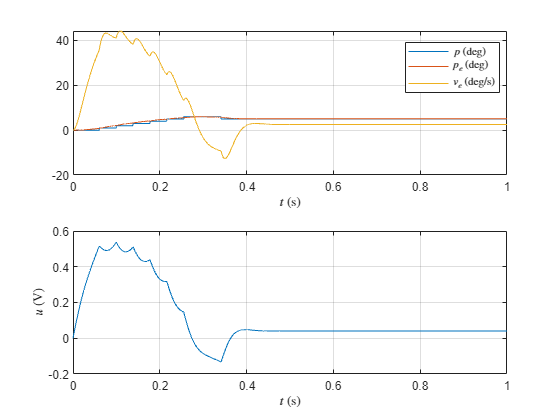

poles_ri_disc = exp([-0.03*p -0.035*p -0.04*p]*T);

K_ri_disc = place(F_ri,G_ri,poles_ri_disc);
K_r_disc = K_ri_disc(1:2);
K_i_disc = K_ri_disc(3);
poles_e_disc = exp([-0.065*p -0.06*p]*T);
L_disc = place(F',C',poles_e_disc)';

simOut = sim('controller_disc.slx');
time = simOut.tout;
angPos = simOut.yout{1}.Values.Data;
voltage = simOut.yout{3}.Values.Data;
angPosEst = simOut.yout{4}.Values.Data;
angVelEst = simOut.yout{5}.Values.Data;

figure
subplot(2,1,1)
plot(time,angPos)
hold on
plot(time,angPosEst)
plot(time,angVelEst)
grid on
legend('$p$ (deg)','$p_e$ (deg)','$v_e$ (deg/s)', Location="best", Interpreter='latex')
xlabel('$t$ (s)', Interpreter='latex')
xlim([0 1])
subplot(2,1,2)
plot(time,voltage)
grid on
xlabel('$t$ (s)', Interpreter='latex')
ylabel('$u$ (V)', Interpreter='latex')
xlim([0 1])
exportgraphics(gcf,'figuras\controlLentoDisc.pdf')

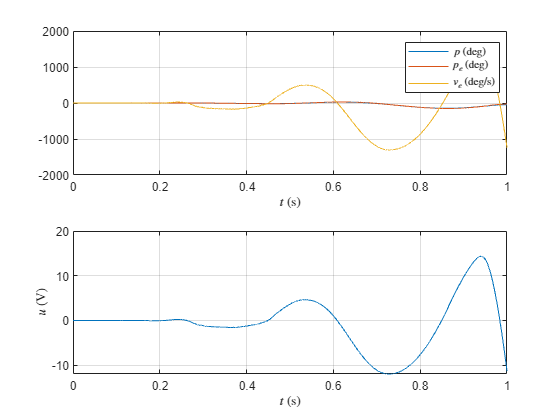

poles_ri_disc = exp([-3*p -3.5*p -4*p]*T);
K_ri_disc = place(F_ri,G_ri,poles_ri_disc);

K_r_disc = K_ri_disc(1:2);
K_i_disc = K_ri_disc(3);
poles_e_disc = exp([-6.5*p -6*p]*T);
L_disc = place(F',C',poles_e_disc)';

simOut = sim('controller_disc.slx');
time = simOut.tout;
angPos = simOut.yout{1}.Values.Data;
voltage = simOut.yout{3}.Values.Data;
angPosEst = simOut.yout{4}.Values.Data;
angVelEst = simOut.yout{5}.Values.Data;

figure
subplot(2,1,1)
plot(time,angPos)
hold on
plot(time,angPosEst)
plot(time,angVelEst)
grid on
legend('$p$ (deg)','$p_e$ (deg)','$v_e$ (deg/s)', Location="best", Interpreter='latex')
xlabel('$t$ (s)', Interpreter='latex')
xlim([0 1])
subplot(2,1,2)
plot(time,voltage)
grid on
xlabel('$t$ (s)', Interpreter='latex')
ylabel('$u$ (V)', Interpreter='latex')
xlim([0 1])
exportgraphics(gcf,'figuras\controlRapidoDisc.pdf')

Con diferentes constantes de anti wind-up.

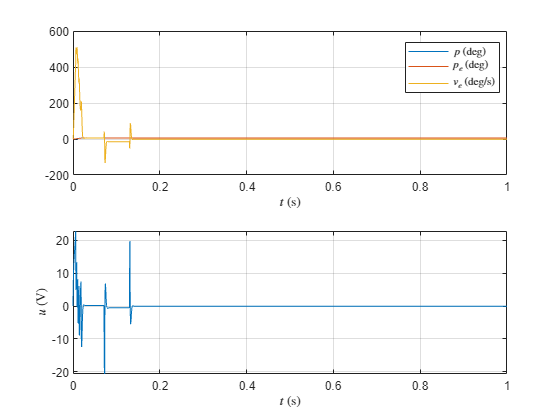

poles_ri_disc = exp([-4*p -4.1*p -4.2*p]*T);
K_ri_disc = place(F_ri,G_ri,poles_ri_disc);
K_r_disc = K_ri_disc(1:2);

K_i_disc = K_ri_disc(3);
poles_e_disc = exp([-5*p -5.1*p]*T);
L_disc = place(F',C',poles_e_disc)';
accInt = 1;
accDirDisc = 0;
k_awp = 0.1;
simOut = sim('controller_disc.slx');
time = simOut.tout;
angPos = simOut.yout{1}.Values.Data;
voltage = simOut.yout{3}.Values.Data;
angPosEst = simOut.yout{4}.Values.Data;
angVelEst = simOut.yout{5}.Values.Data;

figure
subplot(2,1,1)
plot(time,angPos)
hold on
plot(time,angPosEst)
plot(time,angVelEst)
grid on
legend('$p$ (deg)','$p_e$ (deg)','$v_e$ (deg/s)', Location="best", Interpreter='latex')
xlabel('$t$ (s)', Interpreter='latex')
xlim([0 0.1])
subplot(2,1,2)
plot(time,voltage)
grid on
xlabel('$t$ (s)', Interpreter='latex')
ylabel('$u$ (V)', Interpreter='latex')
xlim([0 0.1])
exportgraphics(gcf,'figuras\antiWindUpFlojo.pdf')

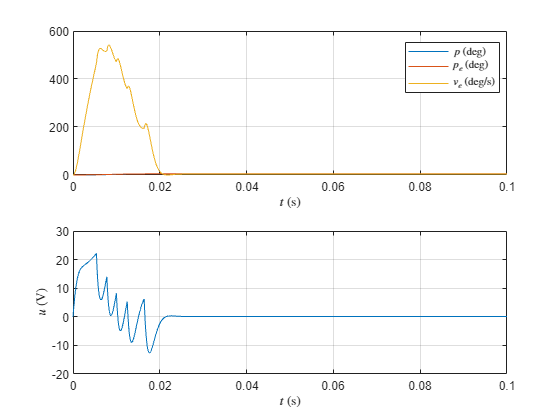

k_awp = 0.2;
simOut = sim('controller_disc.slx');
time = simOut.tout;
angPos = simOut.yout{1}.Values.Data;
voltage = simOut.yout{3}.Values.Data;

angPosEst = simOut.yout{4}.Values.Data;
angVelEst = simOut.yout{5}.Values.Data;

figure
subplot(2,1,1)
plot(time,angPos)
hold on
plot(time,angPosEst)
plot(time,angVelEst)
grid on
legend('$p$ (deg)','$p_e$ (deg)','$v_e$ (deg/s)', Location="best", Interpreter='latex')
xlabel('$t$ (s)', Interpreter='latex')
xlim([0 0.1])
subplot(2,1,2)
plot(time,voltage)
grid on
xlabel('$t$ (s)', Interpreter='latex')
ylabel('$u$ (V)', Interpreter='latex')
xlim([0 0.1])
exportgraphics(gcf,'figuras\antiWindUpMedio.pdf')

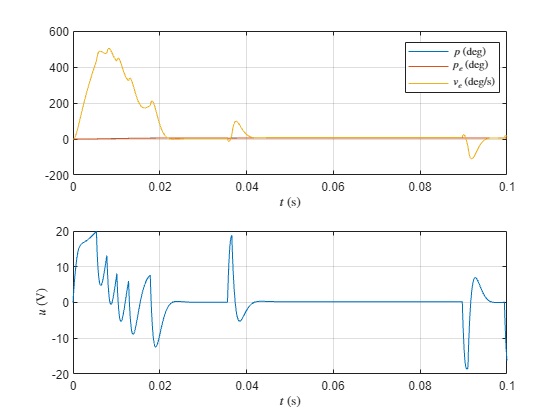

k_awp = 0.5;
simOut = sim('controller_disc.slx');
time = simOut.tout;
angPos = simOut.yout{1}.Values.Data;
voltage = simOut.yout{3}.Values.Data;
angPosEst = simOut.yout{4}.Values.Data;

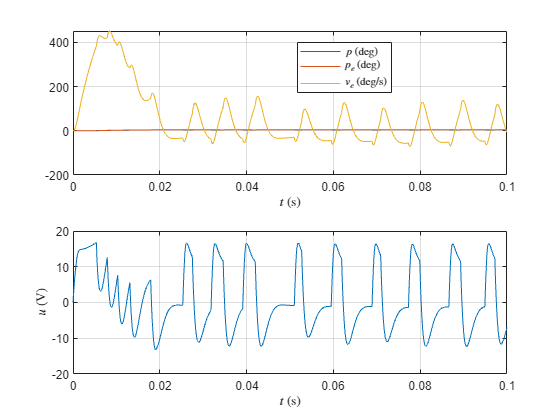

angVelEst = simOut.yout{5}.Values.Data;

figure
subplot(2,1,1)
plot(time,angPos)
hold on
plot(time,angPosEst)
plot(time,angVelEst)
grid on
legend('$p$ (deg)','$p_e$ (deg)','$v_e$ (deg/s)', Location="best", Interpreter='latex')
xlabel('$t$ (s)', Interpreter='latex')
xlim([0 0.1])
subplot(2,1,2)
plot(time,voltage)
grid on
xlabel('$t$ (s)', Interpreter='latex')
ylabel('$u$ (V)', Interpreter='latex')
xlim([0 0.1])
exportgraphics(gcf,'figuras\antiWindUpFuerte.pdf')